# Demo of shadedErrorBar

## Basic Usage

This example shows how to plot the mean and standard deviation using shadedErrorBar.

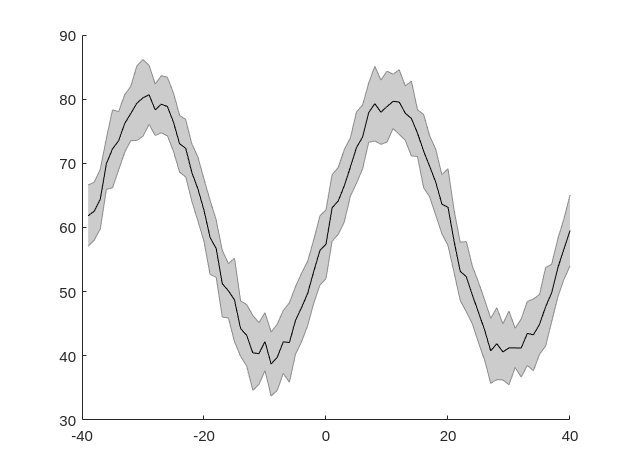

% Generate some random data
clf
y=randn(30,80) * 5;
x=(1:size(y,2)) - 40;
yP = sin( linspace(-2*pi,2*pi,length(x)) ) * 20; % Create a sine wave
y = bsxfun(@plus,y,yP) + 60; % Add the sine wave to the random data and offset the data

% Plot with shaded error bar
shadedErrorBar(x,y,{@mean,@std}); 

The above plot shows the mean as the solid black line and the SD as the grey area around it. We can plot over the top the data that underly this distribution:

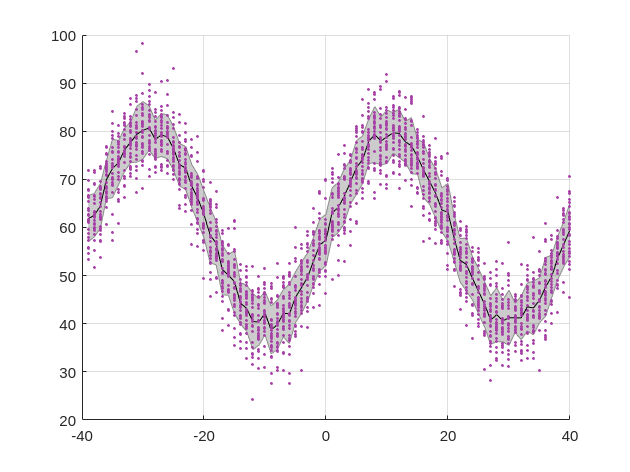

hold on
plot(x,y,'.','color',[0.65,0.25,0.65])
hold off

grid on

## Overlay different lines lines and change their properties

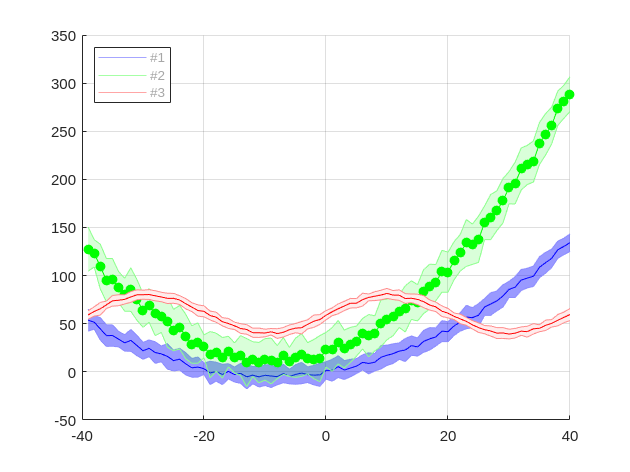

clf
hold on

plot2styles = {'-b';'-g'; '-r'};
for i = 1:3
  plt2invis = plot(0,0,plot2styles{i});
  set( plt2invis, 'visible', 'off'); 
end
  


x=(1:size(y,2))-40;
y=ones(30,1)*x; 
y=y+0.06*y.^2+randn(size(y))*10;
shadedErrorBar(x,y,{@mean,@std},'lineprops','-b','transparent',true,'patchSaturation',0.4)
shadedErrorBar(x,2*y+20,{@mean,@std},'lineprops',{'-go','MarkerFaceColor','g'},'transparent',true,'patchSaturation',0.15);

y=randn(30,80)*5; 
x=(1:size(y,2))-40;
yP = sin( linspace(-2*pi,2*pi,length(x)) )*20;
y = bsxfun(@plus,y,yP)+60;

%Make red line non-transparent
shadedErrorBar(x, y, {@mean,@std}, 'lineprops', '-r','transparent',false,'patchSaturation',0.075)
hold off

legend(['#1';'#2';'#3'],'location','northwest')
legend
grid on

## How to modify plot elements post-hoc

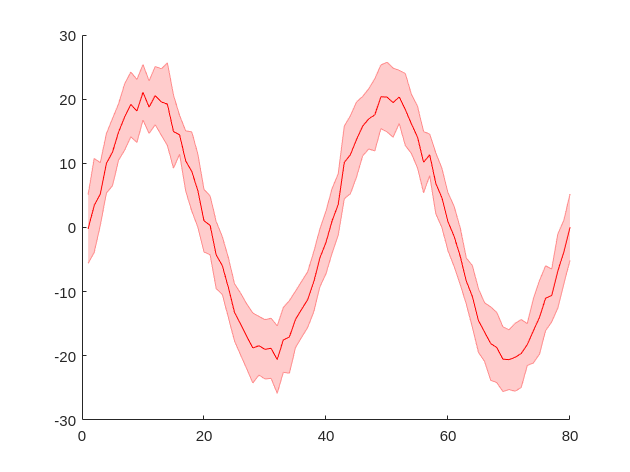

clf

% Generate some random data
y = randn(30,80)*5; 
x = (1:size(y,2));
yP = sin( linspace(-2*pi,2*pi,length(x)) )*20; % Create a sine wave
y = bsxfun(@plus,y,yP); % Add the sine wave to the random data

% Plot with shadedErrorBar and return the plot objects as a structure 
s = shadedErrorBar(x, y, {@mean,@std}, 'lineprops', '-r');

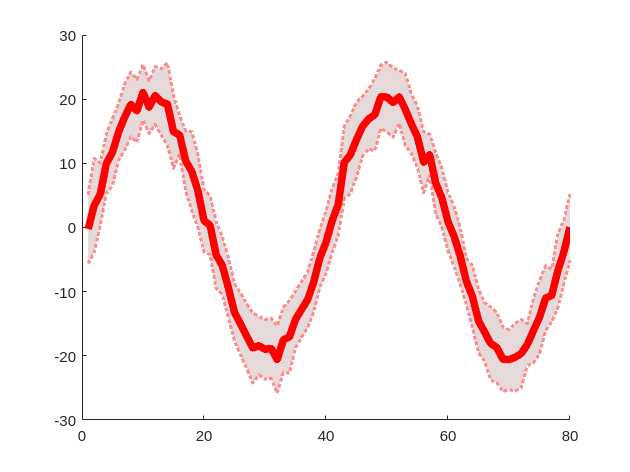

% We now modify the above plot by altering the properties of the plot
% objects in the variable, s. 
set(s.edge,'LineWidth',2,'LineStyle',':')
s.mainLine.LineWidth = 5;
s.patch.FaceColor = [0.5,0.25,0.25];

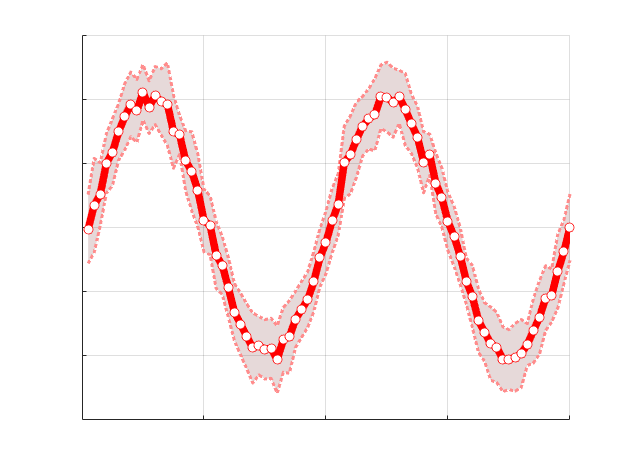

% We now extract the data points underlying the main plot line and use this to 
% to overlay white disks over these points

hold on
plot(s.mainLine.XData, s.mainLine.YData,'or','MarkerFaceColor','w')
hold off

grid on
set(gca,'XTickLabel',[],'YTickLabel',[])

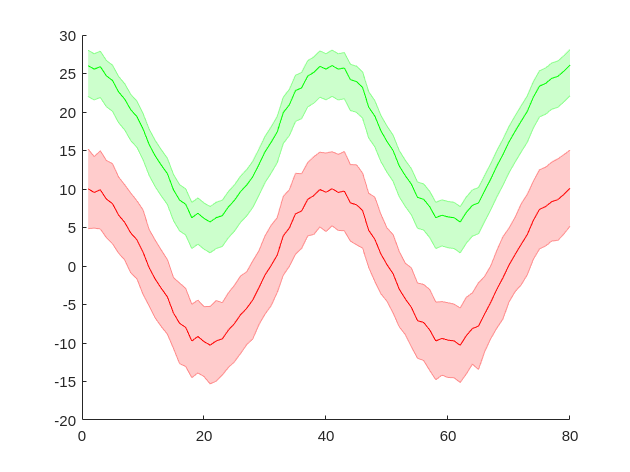




% Post-hoc modifications of line properties
clf

y=randn(256,80)*5; 
x=(1:size(y,2));
yP = cos( linspace(-2*pi,2*pi,length(x)) )*10;
y = bsxfun(@plus,y,yP);


shadedErrorBar(x, y, {@mean,@std}, 'lineprops', '-r')

hold on

y=mean(y)+16;
errbar = [2*ones(1,length(x)) ; 4*ones(1,length(x))];

shadedErrorBar(x, y, errbar, 'lineprops', '-g')